### 1

### 2

### 3

### 4

### 5

### 6

Here, $\mathrm{TP}+\mathrm{FN}=10$equals total number of people with the condition, and $\textrm{FP}+\textrm{TN}=60$equals people without the condition.


$$\begin{array}{l}
\mathrm{Sensitivity}=\frac{\mathrm{TP}}{\mathrm{TP}+\mathrm{FN}}\Rightarrow 0\ldotp 9=\frac{\mathrm{TP}}{10}\Rightarrow \mathrm{TP}=9\\
\mathrm{Specificity}=\frac{\mathrm{TN}}{\mathrm{FP}+\mathrm{TN}}\Rightarrow 0\ldotp 8=\frac{\mathrm{TN}}{60}\Rightarrow \mathrm{TN}=48
\end{array}$$



$$\mathrm{FP}=10-\mathrm{TP}=1$$


### 7

### 8

A represents accuracy, and B represents precision.

### 9

### 10

### Graduate content

1. Generate a set of signals as an n by m array of Gaussian random numbers with a mean of 12 and std of 3.

n = 1024;
m = 10;
targetMean = 12;
targetStd = 3;
x = targetMean + targetStd * randn(m,n);

2. Plot the first record as a time series

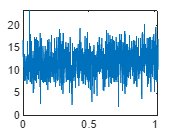

% Plot 1 column
dt = 0.001;
tmax = 1.024;
t = 0:dt:tmax-dt;
figure(1)
plot(t,x(1,:))

3. Ensemble average the m records

xavg = ensemblAvg_2(x);

4. Plot the ensemble averaged signal

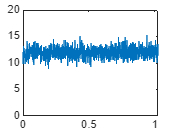

figure(2)
plot(t,xavg)
ylim([0 20])

5. Find the average and std of each of the original signals, and the average and std of the ensemble averaged signal

[means, stds] = stat_2(x);

ensmblMean = mean(xavg);
ensmblStd = std(xavg);

% Create the table
T = table(columnNames, [means; ensmblMean], [stds; ensmblStd], ...
    'VariableNames', {'Column', 'Mean', 'StandardDeviation'});

disp(T);

      Column        Mean     StandardDeviation
    ___________    ______    _________________

    {'1'      }     11.94          3.0012     
    {'2'      }    12.018          2.9856     
    {'3'      }    11.943          3.0115     
    {'4'      }    12.048          3.0244     
    {'5'      }     12.08          2.9163     
    {'6'      }    11.961          3.1808     
    {'7'      }    12.004          2.9408     
    {'8'      }    11.983          3.1089     
    {'9'      }    11.899          3.0528     
    {'10'     }    11.998          3.0342     
    {'Ensembl'}    11.987         0.96723     



6. Compare simulated std to generator std

The target mean was 12, and the means of each of the signal are close to 12. If the number of samples are increased, the means of each signal will get closer to 12. Similar for std of 3.

7. The ensemble signal has std of 0.93141, which is greater than $\sigma_g /m=0\ldotp 3$

8. Running with $\sigma_g /m=100$

n = 1024;
m = 100;
targetMean = 12;
targetStd = 3;
x = targetMean + targetStd * randn(m,n);
xavg = ensemblAvg_2(x);
ensmblMean = mean(xavg)

ensmblMean = 12.0079

ensmblStd = std(xavg)

ensmblStd = 0.2939

This time the std is 0.2939, which is much closer to 0.3